## Extract MS Resource Usage using Map Reduce

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Load Config

If you have not done it yet, copy example_config.m and name the copy config.m and adjust to your options.

Then run this snippet  to load your choices.

[trace_header, trace_vartypes, mapped_trace_vartypes] = constants();
[trace_location, trace_header_lines, ms_by_interfaces_location] = config();

### Prepare selected columns

As we do not care about 'node_id'

used_col_idx = strcmp(trace_header, "node_id") == 0;
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, "VariableNames", trace_header, "RowDelimiter", "\n", "Delimiter", ",", "SelectedVariableNames", trace_selected_cols);
preview(ds)

ans = 8×6 table
     Nr                                   ms_name                                                              ms_instance_id                                 cpu      memory     timestamp
    ____    ____________________________________________________________________    ____________________________________________________________________    _______    _______    _________

     531    {'002251d4123496684687c2acad43bdef9419a5e4fc01a65d2c558af92a5ad649'}    {'dbdab3d08dcf82b602be28ac78199e9b0653574c9024823caf5b16f06ff5faeb'}    0.15833    0.68117     1.5e+05 
    1280    {'002251d4123496684687c2acad43bdef9419a5e4fc01a65d2c558af92a5ad649'}    {'09c77631fe7a47ce52a74f6f21137aa25a6755fcc6175176c4067cbc851ef0c5'}    0.18133    0.68639     4.2e+05 
    1294    {'002251d412349

### Load MS by Interface data

Load matlab file containing the used interfaces and services, extract the list of microservices we are interested in..

load(ms_by_interfaces_location);
used_ms = unique(vertcat(ms_by_svc{:,2}{:}));
clear("ms_by_svc");

### Filter relevant MS

% wrap mapper function to pass variable context
mapFunc = @(a, b, c)filter_ms_mapper(a, b, c, used_ms);

% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 6], 'VariableTypes',mapped_trace_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)filter_ms_reducer(a, b, c, empty_table);
tic
ms_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');

********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map  38% Reduce   0%
Map  76% Reduce   0%
Map 100% Reduce   0%
Map 100% Reduce 100%


### Preview

one = preview(ms_ds)

one = 1×2 table
                                    Key                                          Value     
    ____________________________________________________________________    _______________

    {'002251d4123496684687c2acad43bdef9419a5e4fc01a65d2c558af92a5ad649'}    {52439×6 table}


preview_t = one.Value{1};
preview_ms_inst = preview_t.ms_instance_id{1};
preview_one_inst = preview_t(strcmp(preview_t.ms_instance_id, preview_ms_inst) > 0,:)

preview_one_inst = 120×6 table
       Nr                                    ms_name                                                            ms_instance_id                                cpu      memory     timestamp
    ________    __________________________________________________________________    __________________________________________________________________    _______    _______    _________

     8530096    "002251d4123496684687c2acad43bdef9419a5e4fc01a65d2c558af92a5ad649"    "001842cde63e676b4382c92b3a0e63f8785f03039404a8e2a38629752c8ed7ed"    0.16125    0.68488         0   
      296563    "002251d4123496684687c2acad43bdef9419a5e4fc01a65d2c558af92a5ad649"    "001842cde63e676b4382c92b3a0e63f8785f03039404a8e2a38629752c8ed7ed"    0.16125    0.68488       0.5   
     7869907

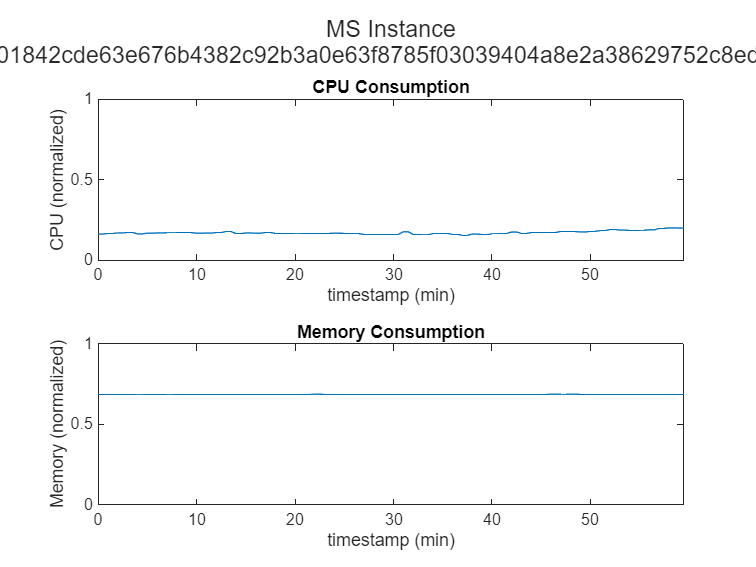

t = tiledlayout(2,1);
cpu_plot = nexttile;
plot(cpu_plot,preview_one_inst, "timestamp","cpu")
title(cpu_plot, "CPU Consumption")
ylabel(cpu_plot, "CPU (normalized)")
xlabel(cpu_plot, "timestamp (min)")

mem_plot = nexttile;
plot(mem_plot,preview_one_inst, "timestamp","memory")
title(mem_plot, "Memory Consumption")
ylabel(mem_plot, "Memory (normalized)")
xlabel(mem_plot, "timestamp (min)")

% un-comment line below to plot Y-Value from 0-1
axis([cpu_plot mem_plot],[0 Inf 0 1])
title(t, sprintf("MS Instance\n%s", preview_ms_inst))

### TODO